### AAE340

### Tomoki Koike 

### Matlab Assignments

## 1e.

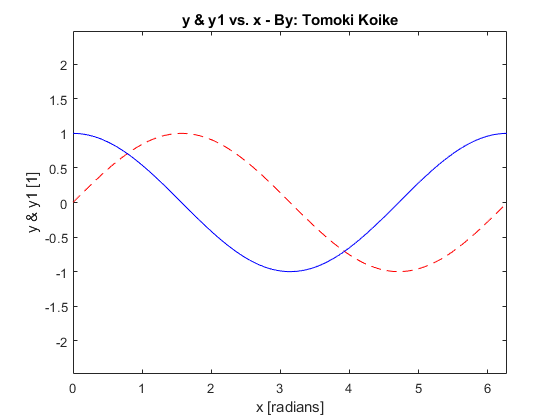

% ---EXAMPLE 7---
x0 = 0;
xf = 2*pi;
xstep = 0.01;
x = x0:xstep:xf;
y1 = sin(x);
y2 = cos(x);
% Plotting
figure(1)
plot(x,y1,'r--',x,y2,'b')
xlabel('x [radians]')
ylabel('y & y1 [1]')
axis('equal')
title('y & y1 vs. x - By: Tomoki Koike')

## 1f.

% Solve the ODE for the analytical solution 
syms x(t);
zeta = 0.5;
omega_not = 1;
D2x = diff(x,t,2);
Dx = diff(x,t);
ode = D2x + 2 * zeta * omega_not * Dx == 0;
cond1 = x(0) == 1;
cond2 = Dx(0) == 0;
conds = [cond1 cond2];
xsol(t) = dsolve(ode, conds);
% Plotting 

$$1$$

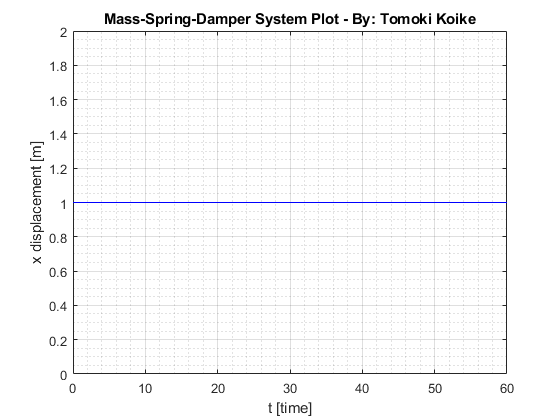

t0 = 0;
tf = 60;
tstep = 0.01;
t = t0:tstep:tf;
figure(2)
plot(t, xsol(t), 'b-')
xlabel('t [time]')
ylabel('x displacement [m]')
title('Mass-Spring-Damper System Plot - By: Tomoki Koike')
grid on
grid minor
box on